# **LAB 3**

# **Mohamed Ahmed Mahmoud Menazaa - 18011370**

## **( 1 ) **


% Given system equation
numerator = [18, 8];
denominator = [1, -1, 0];  % Z^2 - Z

% Transfer function
sys = tf(numerator, denominator);

% Impulse response
num_points = 10;
impulse_response = impulse(sys, (0:num_points-1));

% Step response
step_response = step(sys, (0:num_points-1));

% Display transfer function
disp('Transfer Function:');

Transfer Function:


disp(sys);

  tf with properties:

       Numerator: {[0 18 8]}
     Denominator: {[1 -1 0]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Display impulse response
disp('Impulse Response:');

Impulse Response:


disp(impulse_response);

   1.0e+05 *

    0.0002
    0.0006
    0.0018
    0.0051
    0.0141
    0.0385
    0.1048
    0.2850
    0.7750
    2.1067




% Display step response
disp('Step Response:');

Step Response:


disp(step_response);

   1.0e+05 *

         0
    0.0004
    0.0015
    0.0047
    0.0136
    0.0379
    0.1042
    0.2843
    0.7741
    2.1058



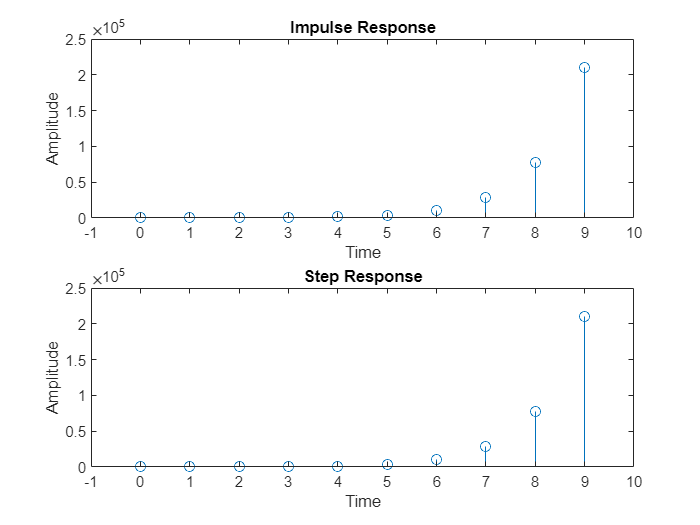


% Plot responses
figure;
subplot(2,1,1);
stem(0:num_points-1, impulse_response);
title('Impulse Response');
xlabel('Time');
ylabel('Amplitude');

xlim([-1 10]);

subplot(2,1,2);
stem(0:num_points-1, step_response);
title('Step Response');
xlabel('Time');
ylabel('Amplitude');
xlim([-1 10]);

## **( 2 ) **

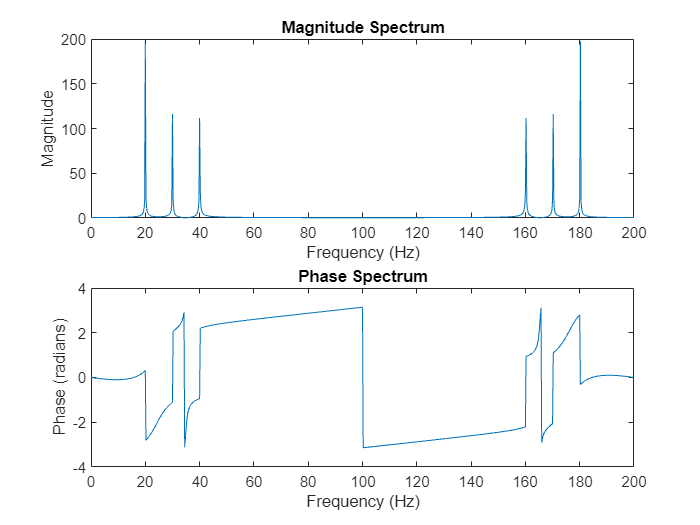


% Parameters
Fs = 200;  % Sampling frequency
T = 1/Fs;  % Sampling period
t = 0:T:4;  % Time vector

% Given signal
x_t = 0.5*cos(40*pi*t) + 0.3*sin(60*pi*t) + 0.3*sin(80*pi*t);

% Compute the Fourier transform
X_f = fft(x_t);
frequencies = linspace(0, Fs, length(X_f));

% Plot magnitude spectrum
figure;
subplot(2, 1, 1);
plot(frequencies, abs(X_f));
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot phase spectrum
subplot(2, 1, 2);
plot(frequencies, angle(X_f));
title('Phase Spectrum');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');

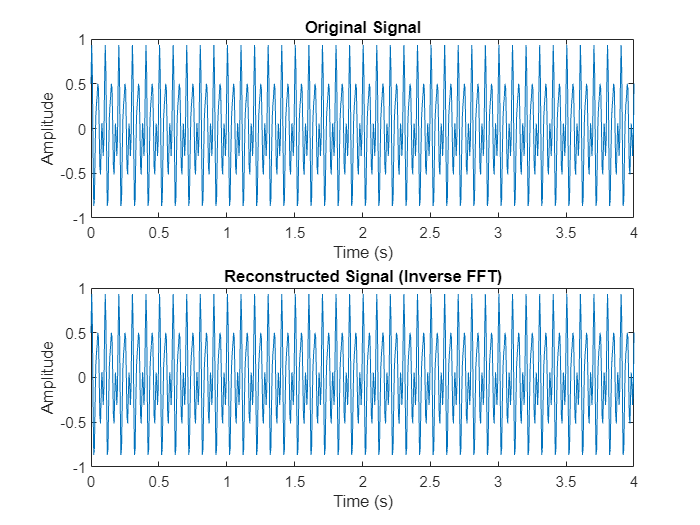


% Transform the signal back to time domain
x_reconstructed = ifft(X_f);

% Plot the original and reconstructed signals
figure;
subplot(2, 1, 1);
plot(t, x_t);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(t, x_reconstructed);
title('Reconstructed Signal (Inverse FFT)');
xlabel('Time (s)');
ylabel('Amplitude');

## ( 3 )

% Given signals
x1 = [1, 2, 0, 1];
x2 = [2, 2, 1, 1];

% Method 1: Convolution using conv function
conv_result_conv = conv(x1, x2);

% Method 2: Convolution using FFT and IFFT
N = length(x1) + length(x2) - 1;
X1 = fft(x1, N);
X2 = fft(x2, N);
conv_result_fft = ifft(X1 .* X2);
conv_result_fft = round(conv_result_fft);

% Display and compare results
disp('Convolution Result using conv function:');

Convolution Result using conv function:


disp(conv_result_conv);

     2     6     5     5     4     1     1




disp('Convolution Result using FFT and IFFT:');

Convolution Result using FFT and IFFT:


disp(conv_result_fft);

     2     6     5     5     4     1     1




% Compare results
if isequal(conv_result_conv, conv_result_fft)
    disp('Results are equal.');
else
    disp('Results are not equal.');
end

Results are equal.


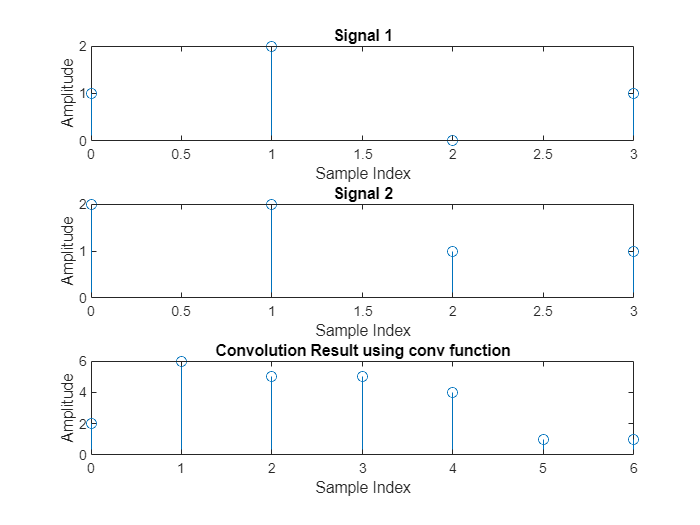



% Plot the signals and convolution results
figure;

% Plot Signal 1
subplot(3, 1, 1);
stem(0:length(x1)-1, x1);
title('Signal 1');
xlabel('Sample Index');
ylabel('Amplitude');

% Plot Signal 2
subplot(3, 1, 2);
stem(0:length(x2)-1, x2);
title('Signal 2');
xlabel('Sample Index');
ylabel('Amplitude');

% Plot Convolution Result using conv function
subplot(3, 1, 3);
stem(0:length(conv_result_conv)-1, conv_result_conv);
title('Convolution Result using conv function');
xlabel('Sample Index');
ylabel('Amplitude');

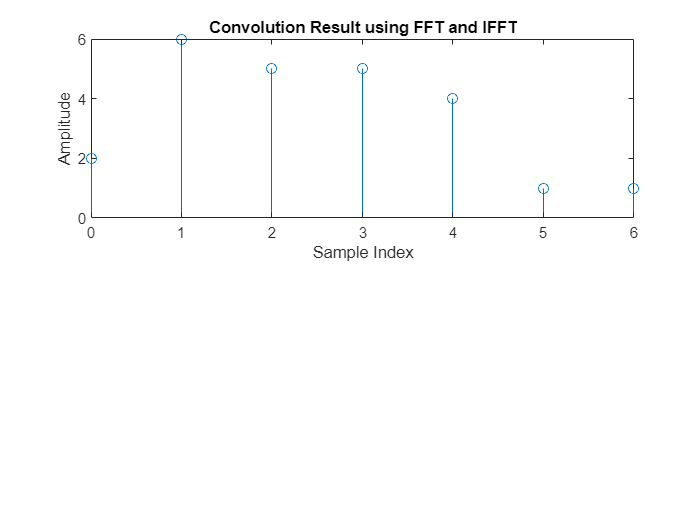


% Plot Convolution Result using FFT and IFFT
figure;
subplot(2, 1, 1);
stem(0:length(conv_result_fft)-1, conv_result_fft);
title('Convolution Result using FFT and IFFT');
xlabel('Sample Index');
ylabel('Amplitude');

## ( 4 )

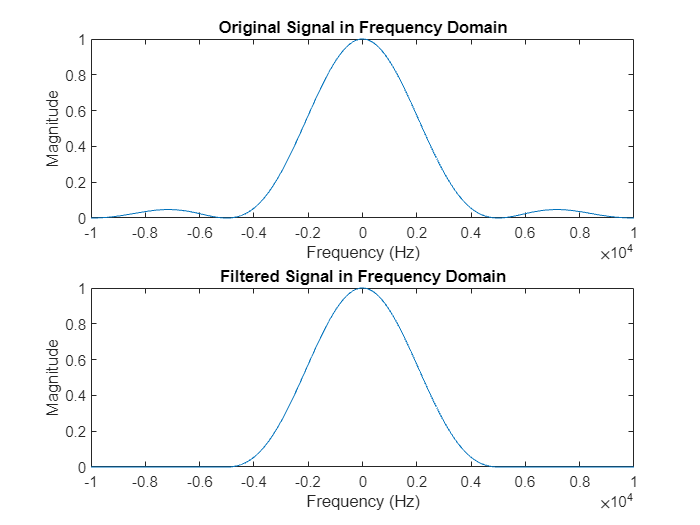

% Parameters
fs = 20000;         % Sampling frequency (20 kHz)
Ns = 100000;        % Number of samples
f = linspace(-fs/2, fs/2, Ns);  % Frequency vector

% Define the signal in frequency domain
X_f = sinc(f/5000) .* sinc(f/5000);

% Plot the original signal in frequency domain
figure;
subplot(2, 1, 1);
plot(f, abs(X_f));
title('Original Signal in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-10e3 10e3]);

% Eliminate frequency components outside the range [-5 kHz, 5 kHz]
X_f_filtered = X_f;
X_f_filtered(abs(f) > 5000) = 0;

% Plot the filtered signal in frequency domain
subplot(2, 1, 2);
plot(f, abs(X_f_filtered));
title('Filtered Signal in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-10e3 10e3]);

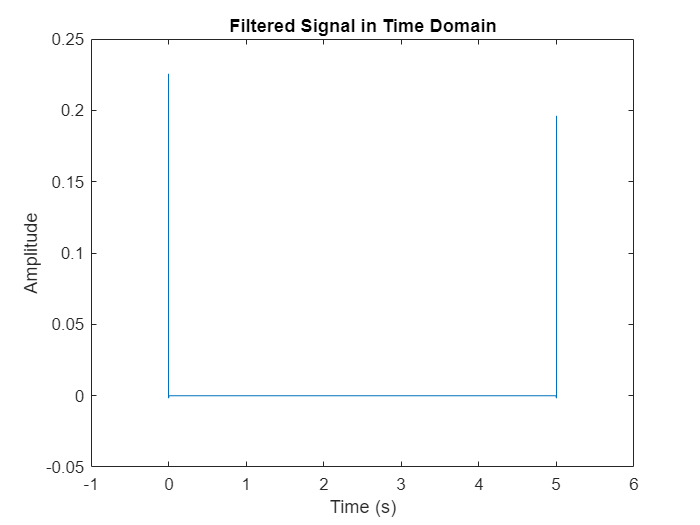


% Transform back to time domain using IFFT
x_t_filtered = ifft(ifftshift(X_f_filtered));

% Plot the filtered signal in time domain
figure;
plot((0:Ns-1) / fs, real(x_t_filtered));
title('Filtered Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([-1 6]);